# Estudio de separabilidad de un punto

En este script vamos a tratar de determinar en base a un ejemplo lo siguiente. Tomamos $N$ puntos aleatorios en $B(0,1)$, de los cuales elegimos uno arbitrario, llamémosle de clase A y a los demás de clase B. ¿Cómo hay que elegir un hiperplano de froma que haya el menor número de puntos posible de clase B en la sección del plano en la que se encuentra el punto de clase A?

Como estamos en el contexto de un perceptrón, tenemos, además, un vector de pesos $w \in \mathbb{R}^n$.

## Separabilidad de 2 puntos

Empecemos con tan sólo dos puntos y veamos cómo evoluciona la probabilidad de separarlos.

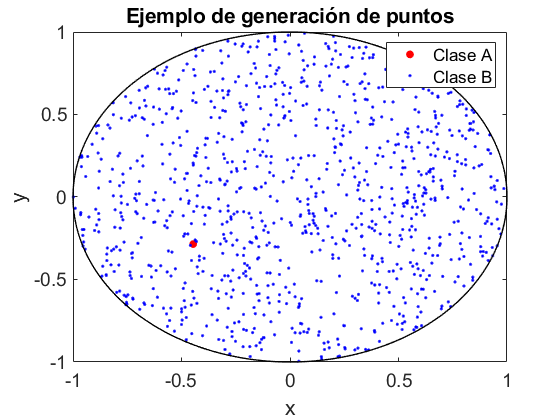

[X, Y] = generatePoints(1000, 2, 1);

% Dibujamos los puntos generados
plotPoints(X, Y, 'Ejemplo de generación de puntos');
legend({'Clase A', 'Clase B'});
hold off

Empezamos tomando un hiperplano (una recta en este caso) de la forma $H \equiv w \cdot x = \theta$, donde $\theta \in (0,1)$ y $w \in \mathbb{R}^n$, un vector que podemos suponer que tiene un ángulo cercano al de $x_1$, pues debería provenir de un perceptrón ya entrenado, pero norma arbitraria. El parámetro $\theta$ lo vamos a elegir suficientemente pequeño para que $x_1$ cumpla $w \cdot x_1 > \theta$. Debería bastar con algo menor que el cateto de un triángulo rectángulo formado por $0$, $x_1$ y la proyección de $x_1$ sobre $w$.

Ahora, definamos $A = \{x \in B_n(0, 1) : w \cdot x > \theta\}$, el espacio que queda comprendido "por encima" de $H$, dentro de la bola y sabemos que $\text{dist}(0, A) = \frac{\theta}{\|w\|}$.

Podemos calcular la probabilidad de que los dos puntos hayan quedado separados de la siguiente forma:

    $P(\text{sep}(x_1, x_2)) = 1 - \frac{V(A)}{V(B_n(0,1))}$.

El volumen de $A$ es difícil de calcular, pero podemos utulizar el hecho de que sabemos que es menor o igual que el de media bola de radio $r = \sqrt{1 - \frac{\theta^2}{\|w\|^2}}$, por Pitágoras. Así,

    $P(\text{sep}(x_1, x_2) \geq 1 - \frac{\frac{1}{2}V(B_n(0, r))}{V(B_n(0, 1))}$.

Por otro lado, sabemos (buscar demostración) que $V(B_n(0, r)) =
\frac{1}{2}
\frac{\pi^{n/2}}{\Gamma\Big(\frac{n}{2} + 1\Big)} r^n$.

Por tanto, $P(\text{sep}(x_1, x_2)) \geq 1 - \frac{1}{2} r^n$.

Vamos a calcular empíricamente la probabildad de que dos puntos queden separados por el hiperplano descrito en diferentes dimensiones. Debemos elegir $\theta$ suficientemente pequeño para asegurar que $w \cdot x_1 > \theta$.

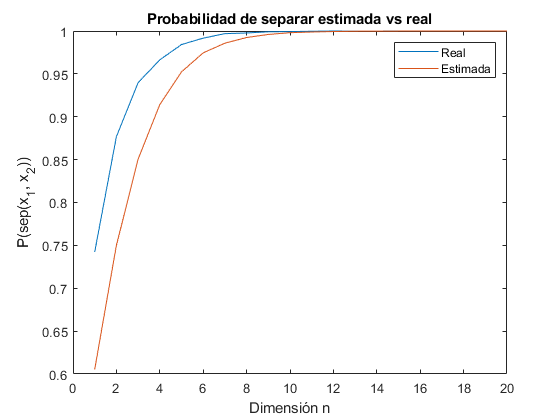

simulate(2, 1:20, 10000, .1)

## Separabilidad de $N$ puntos

Vamos a comprobar ahora cómo escala esta aproximación utilizando un número de puntos $N$ arbitrario.

Recordemos que teníamos que, tomado un punto (distinto de $x_1$), la probabilidad de que estuviera separado por el hiperplano $H$ (el mismo de antes) es

    $p = 1 - \frac{V(A)}{V(B_n(0,1))}$.

Podemos repetir este proceso de comprobación 1 a 1 con los $N-2$ puntos restantes y con esto tendremos $N-1$ experimentos de Bernoulli independientes con probabilidad $p$. Por tanto, si $X$ es una variable aleatoria que representa el número de puntos que quedan separados de $x_1$, con una distribución $B(N-1, p)$.

Así, $P(X=k) = {{N-1}\choose{k}} p^k (1 - p)^{N-1 -k}$.

Como sólo nos interesa el caso $X=N-1$, el cálculo de la probabilidad se simplifica a

    $P(\text{sep}(x_1, X \setminus \{x_1\}) =
P(X=N-1) =
p^{N-1} \geq
\Big(1 - \frac{1}{2} r^n\Big)^{N-1}$.

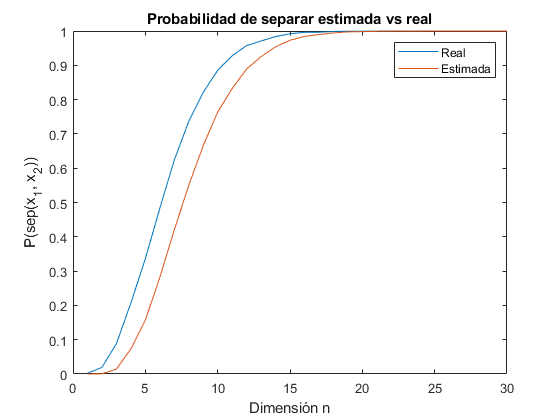

simulate(1000, 1:30, 10000, .1);

Vemos que en este caso necesitamos llegar a dimensiones cercanas 20 para conseguir separar todos los puntos con probabilidad 1, mientras que en el caso anterior (con dos puntos) bastaba con dimensiones en torno a 10. En cualquier caso, se tiene una convergencia bastante alta.

function simulate(N, ns, M, dw)
    estimatedPs = zeros(1, size(ns, 1));
    realPs = zeros(1, size(ns, 1));
    
    for n = ns
        estimatedP = 0;
        realP = 0;
        for m = 1:M
            [X, Y] = generatePoints(N, n, 1);
            x1 = X(Y == 1, :);
            x2 = X(Y == -1, :);
            
            % Elegimos w "cercano" a x1 y ajustamos theta
            w = randsphere(1, n, dw) + x1;
            w = w * (rand * 1.5 + .5);
            % (theta/|w|) / |x1| = cos (w, x1) = (w*x1) / (|w|*|x1|)
            % theta < w * x1
            theta = dot(w, x1) - eps;
            
            H = @(x) w * x' - theta;
            realP = realP + all(sign(H(x1)) ~= sign(H(x2)));
            
            r = sqrt(1 - (theta / norm(w))^2);
            estimatedP = estimatedP + (1 - 1/2 * r^n)^(N - 1);
        end
        
        estimatedPs(n) = estimatedP / M;
        realPs(n) = realP / M;
    end
    
    figure
    plot(realPs);
    hold on
    plot(estimatedPs);
    title('Probabilidad de separar estimada vs real');
    xlabel('Dimensión n');
    ylabel('P(sep(x_1, x_2))');
    legend({'Real', 'Estimada'});
    hold off
end

function X = randsphere(m, n, r)
    % https://es.mathworks.com/matlabcentral/fileexchange/9443-random-points-in-an-n-dimensional-hypersphere
    X = randn(m, n);
    s2 = sum(X.^2, 2);
    X = X.* repmat(r * (gammainc(s2/2, n/2).^ (1/n))./ sqrt(s2), 1, n);
end

function [X, Y] = generatePoints(N, n, A)
    X = randsphere(N, n, 1);
    Y = ones(N, 1);
    indices = randsample(N, N - A);
    Y(indices) = -1;
end

function plotPoints(X, Y, titleText)
    ball = @(rho, theta) [rho.* cos(theta); rho.* sin(theta)];
    frontier = @(theta) ball(1, theta);
    
    plotThetas = linspace(0, 2 * pi, 1000);
    plotFrontier = frontier(plotThetas);
    
    A = Y == 1;
    
    figure
    % Punto de clase A
    plot(X(A, 1), X(A, 2), 'r.', 'MarkerSize', 20);
    hold on
    plot(X(~A, 1), X(~A, 2), 'b.', 'MarkerSize', 5);
    plot(plotFrontier(1, :), plotFrontier(2, :), 'LineWidth', 1, ...
        'Color', 'k', 'HandleVisibility', 'off');
    set(gca, 'FontSize', 14);
    title(titleText);
    xlabel('x');
    ylabel('y');
end